A=[-9 0;0 -8];
B=[-10 1;-2 -7];
C=[2.5 -4.5;2.5 -6.5];
I=eye(2);

#### **1.Вычислить матричные инварианты (собственные значения, определитель и след матрицы**

% Собственных значений матриц
syms l t x
detA=det(l*I-A)

$$detA = \left(l+8\right)\,\left(l+9\right)$$

detB=det(l*I-B)

$$detB = l^{2}+17\,l+72$$

detC=det(l*I-C)

$$detC = l^{2}+4\,l-5$$

eA=solve(detA)

$$eA = \left(\begin{array}{c} -9\\ -8 \end{array}\right)$$

eB=solve(detB)

$$eB = \left(\begin{array}{c} -9\\ -8 \end{array}\right)$$

eC=solve(detC)

$$eC = \left(\begin{array}{c} -5\\ 1 \end{array}\right)$$

% Определители матриц
det(A)

ans = 72

det(B)

ans = 72

det(C)

ans = -5

% Следы матриц
trace(A)

ans = -17

trace(B)

ans = -17

trace(C)

ans = -4

#### **2.Вычислить матричные неинварианты (собственные векторы, нормы матриц, сингулярные числа и числа обусловленности)**

% Собственные векторы Q
[QA,WA]=eig(A)

QA =      1     0
     0     1


WA =     -9     0
     0    -8



[QB,WB]=eig(B)

QB =    -0.7071   -0.4472
   -0.7071   -0.8944


WB =     -9     0
     0    -8


[QC,WC]=eig(C);

% Нормы матриц
sqrt(A(1,1)^2+A(1,2)^2+A(2,1)^2+A(2,2)^2)

ans = 12.0416

sqrt(B(1,1)^2+B(1,2)^2+B(2,1)^2+B(2,2)^2)

ans = 12.4097

sqrt(C(1,1)^2+C(1,2)^2+C(2,1)^2+C(2,2)^2)

ans = 8.6603


a= sqrt(solve(det(t*I-transpose(A)*A)))

$$a = \left(\begin{array}{c} 8\\ 9 \end{array}\right)$$

b = sqrt(solve(det(t*I-transpose(B)*B)))

$$b = \left(\begin{array}{c} \sqrt{77-\sqrt{745}}\\ \sqrt{\sqrt{745}+77} \end{array}\right)$$

c = sqrt(solve(det(t*I-transpose(C)*C)))

$$c = \left(\begin{array}{c} \sqrt{\frac{75}{2}-\frac{5\,\sqrt{221}}{2}}\\ \sqrt{\frac{5\,\sqrt{221}}{2}+\frac{75}{2}} \end{array}\right)$$

% Cингулярные числа
svdA=svd(A)

svdA =      9
     8


svdB=svd(B)

svdB =    10.2125
    7.0502


svdC=svd(C)

svdC =     8.6409
    0.5786


% Числа обусловленности
svdA(1)/svdA(2)

ans = 1.1250

svdB(1)/svdB(2)

ans = 1.4485

svdC(1)/svdC(2)

ans = 14.9330

#### **3. Определить, какие из матриц являются подобными**

$\mathrm{det}{\left(A\right)}=\mathrm{det}{\left(B\right)}$ ⇒ Матрицы А и В подобны

#### **4) Определить алгебраическую и геометрическую кратности собственных значений**


$$\sigma {\left(A\right)}=\sigma {\left(B\right)}={\left\{\lambda_1 =-9;\lambda_2 =-8:\lambda^2 +17\lambda +72\right\}}$$



$$\sigma {\left(C\right)}={\left\{\lambda_1 =-5;\lambda_2 =-1:\lambda^2 +4\lambda -5\right\}}$$


#### 5. Построить отображения единичной сферы 

% Построить отображения единичной окружности в эллипсоиды 
% Построить окружностю
r=1;
x0 = [0;0];
alpha = 0:pi/100:2*pi; 
xunit = [cos(alpha); sin(alpha)];
x = r*xunit + x0; % построение окружности

% Построить эллипсоид
y = B*x; % отображение в эллипсоиды через матрицу
[U,S,V] = svd(B) % используя svd

U =    -0.9694   -0.2457
   -0.2457    0.9694


S =    10.2125         0
         0    7.0502


V =     0.9973    0.0735
    0.0735   -0.9973


clear diag
diag = diag(S); % Cингулярные числа
long_axis = U(:,1)*diag(1,:) % длинная полуось

long_axis =    -9.8995
   -2.5089


short_axis = U(:,2)*diag(2,:) % короткая полуось

short_axis =    -1.7320
    6.8341


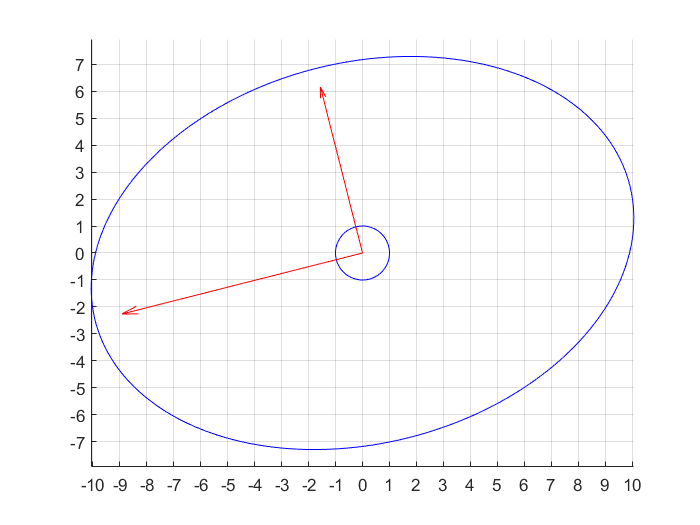

grid on

% Нарисовать
hold on
plot(x(1,:), x(2,:), 'bl'); % окружность
plot(y(1,:), y(2,:), 'bl'); % эллипсоид

quiver(0,0,long_axis(1),long_axis(2),'r'); % окружность стрелка
quiver(0,0,short_axis(1),short_axis(2),'r'); % короткая стрелка
axis equal
set(gca,'xtick',-10:1:10,'ytick',-10:1:10);
hold off